# **PID制御による比例ゲインと系の応答**

clear

g  = 9.81;
l  = 0.2;
M  = 0.5;
mu = 1.5e-2;
J  = 1.0e-2;

P = tf( [0,1], [J, mu, M*g*l] );

ref = 30;

kp = 2

kp = 2

ki = [0, 5, 10]

ki =      0     5    10


kd = 0.1

kd = 0.1000

param = 2

param = 2

max = 8

max = 8

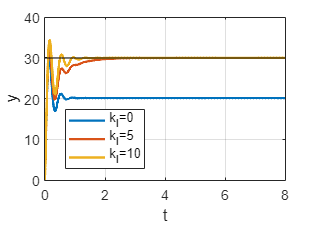

t = 0:0.01:max;
figure();
for i = 1:1:size(ki,2)
    K = tf([kd, kp, ki(i)], [1, 0]);
    Gyr = feedback(P*K, 1);
    y = step( Gyr, t);
    plot(t,y*ref, 'linewidth', 2, 'DisplayName','k_I='+string(ki(i)))
    hold on;
end
plot_set(gcf, 't', 'y', 'best')
plot(t, ref*ones(1,size(t,2)), 'k');

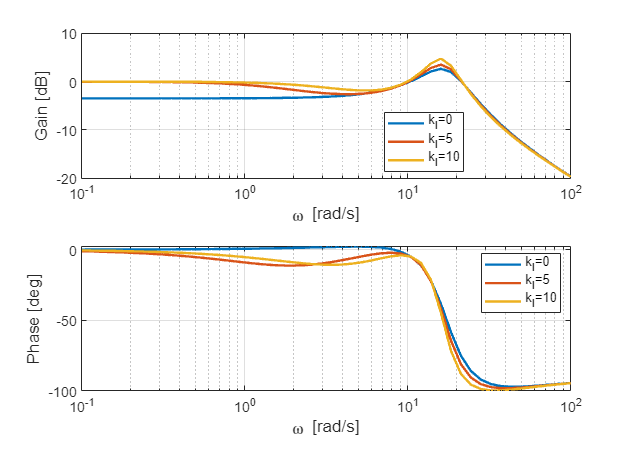

figure();
for i=1:1:size(ki,2)
    K = tf([kd, kp, ki(i)], [1, 0]);
    Gyr = feedback(P*K, 1);
    [gain, phase, w] = bode(Gyr, logspace(-1,2));
    
    gainLog = 20*log10(gain(:));
    phaseDeg = phase(:);
    
    subplot(2,1,1);
    semilogx(w, gainLog, 'LineWidth', param, 'DisplayName','k_I='+string(ki(i)));
    hold on;
    subplot(2,1,2);
    semilogx(w, phaseDeg, 'LineWidth', param, 'DisplayName','k_I='+string(ki(i)));
    hold on;

end
subplot(2,1,1); bodeplot_set(gcf, '\omega [rad/s]', 'Gain [dB]', 'best');
subplot(2,1,2); bodeplot_set(gcf, '\omega [rad/s]', 'Phase [deg]', 'best');